## Desarrollo Tarea 2 Control por Computadora.

#### Juan José Torres Quiñonez 

#### 220160099.

- Se pide diseñar el control en forma de velocidad o posición.

- Debe ser por realimentación de estados discretos.

#### Realimentación de estados:

Pasos:

-  Elegir polos. acker. con bessel o itae, code grado 2 

-  Discretizar polos con $z=e^{\textrm{Ts}}$ con un Ts elegido.

-  Aumentar las matrices (fórmula).

-  Integrador?

-  K1 & K2 son las ganacias de los primeros estados. K3 es la ganancia de los polos aumentados (integrador). Todo debe quedar en términos de " -K ".

-  En la ganancia del intergador se usa una "preganancia" porque si no da problemas.

----------------------------------------

Representación matemática del sistema obtenida de diapositiva:

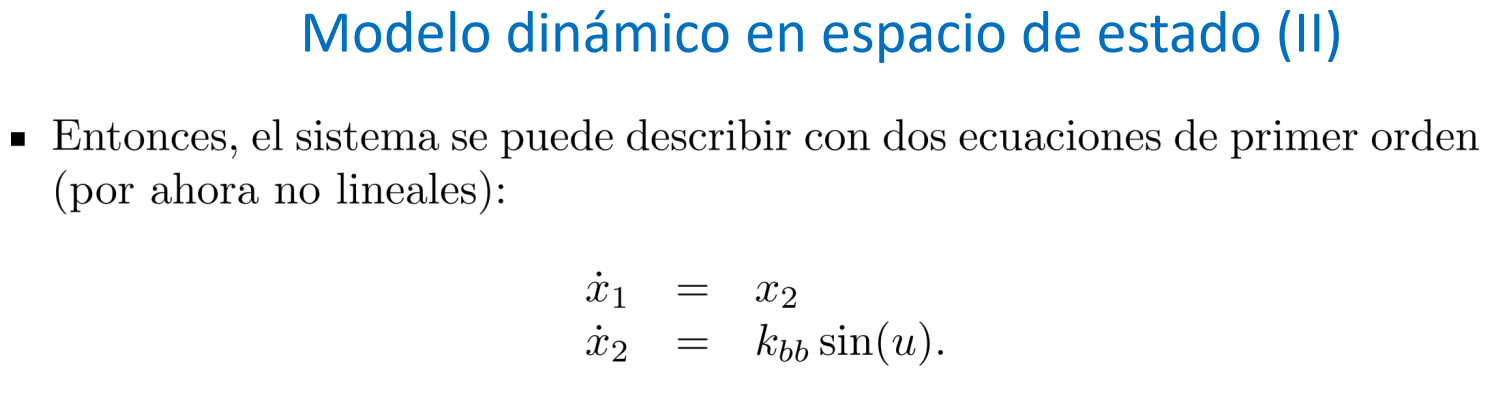

syms x [2 1] 
syms u k_bb r %define variables simbólicas como simbólicas.
f=[x2;k_bb*sin(u)];

Para la linealización se tiene:

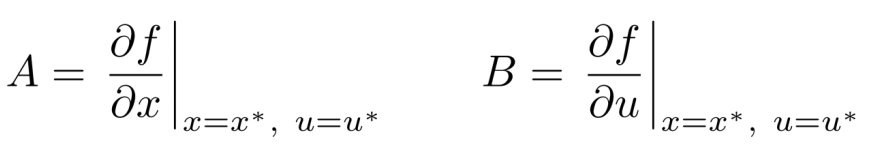

Aplico jacobianos teniendo en cuenta que el típico sistema lineal tiene la forma:


$$\dot{x} =\mathrm{Ax}+\mathrm{Bu}\ldotp$$


A = jacobian(f,x)

$$A = \left(\begin{array}{cc} 0 & 1\\ 0 & 0 \end{array}\right)$$

B = jacobian(f,u)

$$B = \left(\begin{array}{c} 0\\ k_{\mathrm{bb}}\,\cos\left(u\right) \end{array}\right)$$

Cambio de modo simbólico a numérico:

r_arm=0.0254; L_beam=0.4255; g=9.8; kbb=5*g*r_arm/(7*L_beam); %Parámetros en (SI).
A = double(subs(A,x,[r;0]))

A =      0     1
     0     0


B = double(subs(B,[k_bb,u],[kbb,0]))

B =          0
    0.4179


C = [1 0]

C =      1     0


D = 0

D = 0

Discretizo el sistema:

Ts_ = 0.2; % Defino Periodo muestreo.
modo_continuo = ss(A,B,C,D); %Convierte el filtro digital en una representación del espacio de estados.
modo_discreto = c2d(modo_continuo,Ts_);
A_discreto = modo_discreto.A

A_discreto =     1.0000    0.2000
         0    1.0000


B_discreto = modo_discreto.B

B_discreto =     0.0084
    0.0836


Implemento integrador para eliminar el error de estado estacionario e incrementar la robustez del sistema ante perturbaciones de carga (según diapositva 7):

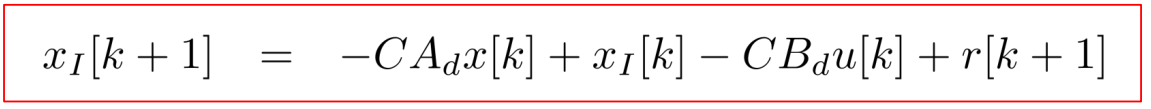

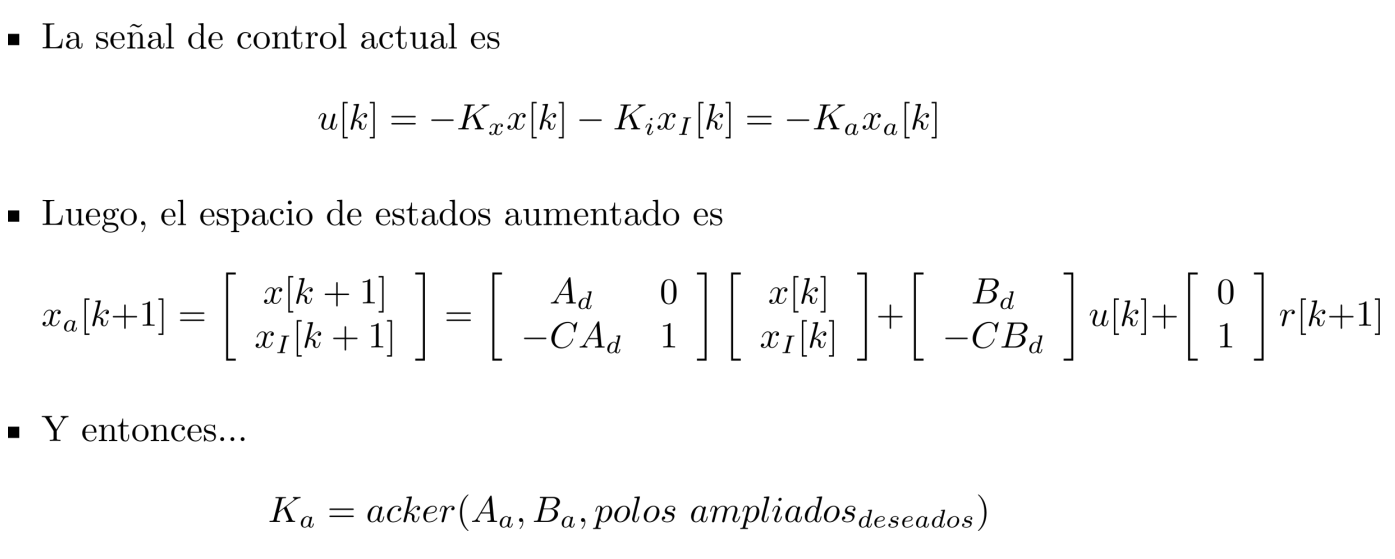

traducido a matlab:

A_discreto_aumentado = [A_discreto, zeros(2,1); -C*A_discreto 1]

A_discreto_aumentado =     1.0000    0.2000         0
         0    1.0000         0
   -1.0000   -0.2000    1.0000


B_discreto_aumentado = [B_discreto; -C*B_discreto]

B_discreto_aumentado =     0.0084
    0.0836
   -0.0084


verificación de controlabilidad:

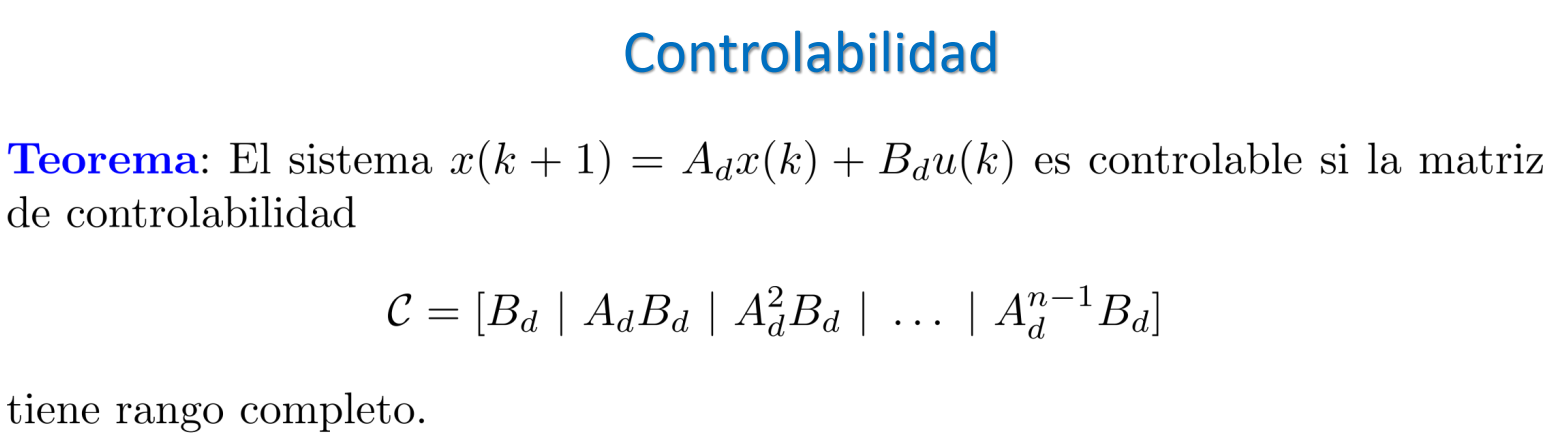

disp("Numero de elementos de A discreta aumentada: " + length(A_discreto_aumentado));

Numero de elementos de A discreta aumentada: 3


disp("Rango matriz controlabilidad: " + rank(ctrb(A_discreto_aumentado,B_discreto_aumentado)));

Rango matriz controlabilidad: 3


disp("Es controlable si el rango es igual al número de estados del sistema.")

Es controlable si el rango es igual al número de estados del sistema.


Para los polos puedo usar la tabla que calcularon o el comando pole:

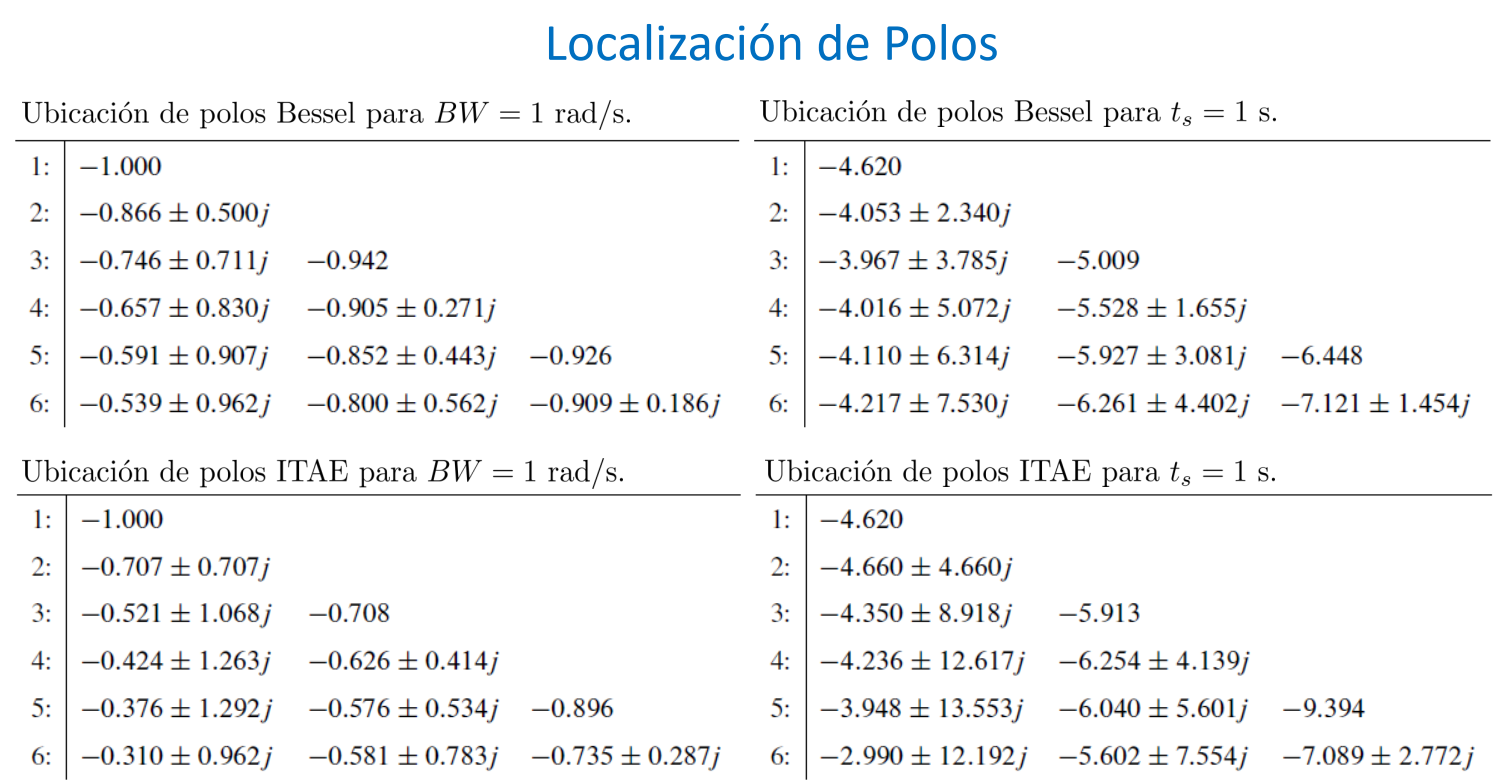

Se pueden obtener los polos en continuo ya que resultan más familiares (tablas), se pasan a dominio discreto con el cambio de coordenadas:


$$z=e^{\textrm{Ts}}$$


% polos=[pole(sistReferencia);-15] %Como la funci de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.
polos_tabla = [-3.967+3.785i, -3.967-3.785i, -5.913]/5; % Polos Bessel dividido entre tiempo asentamiento,  unidades de tiempo.
%polos_tabla = [-4.350+8.918i, -4.350-8.918i, -5.913]/tiempo asentamiento; % Polo Itae

%Calculando polos:
tsdes=10   % Tiempo de asentamiento deseado 23.3 minutos aprox.

tsdes = 10

zita=1  %define si es críticamente amortiguado.

zita = 1

fna=4/(tsdes*zita) %wn=frecNaturalAmortiguada

fna = 0.4000

sistReferencia=tf([0 0 1],[1 2*zita*fna fna^2]);
%polos_tabla=[pole(sistReferencia);-15] %Como la f de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.

polos_discretos = exp(Ts_*polos_tabla)

polos_discretos =    0.8435 + 0.1287i   0.8435 - 0.1287i   0.7894 + 0.0000i


Se ubican los polos discretos deseados con las matrices del sistema discreto.

La ganancia de realimentación se uso ackerman $\textrm{Ka}=\textrm{acker}\left(A_a ,B_a ,\textrm{polos}\;{\textrm{ampliados}}_{\textrm{deseados}} \right)$.

La función acker en MATLAB se utiliza para calcular los valores de las ganancias de realimentación del controlador de un sistema lineal, de modo que los polos del sistema controlado sean los especificados en el vector polos. Calculará las ganancias de realimentación óptimas y devolverá una matriz mat_K que contiene las ganancias necesarias para colocar los polos en las ubicaciones deseadas.

$u\left(t\right)=-\textrm{Kx}\left(t\right)$  donde

- u(t): señal de control

- K: es la matriz de ganancias de realimetación calculada.

- x(t): es eñ vectpr de estadp del sistema.

mat_K=acker(A_discreto_aumentado,B_discreto_aumentado,polos_discretos)  %matriz de ganancias de realimentación K.

mat_K =     5.6242    5.6512   -0.5173


0

Recordando:

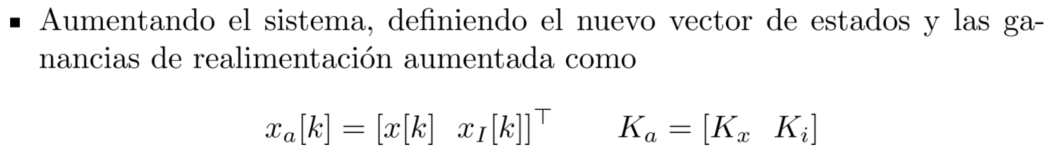

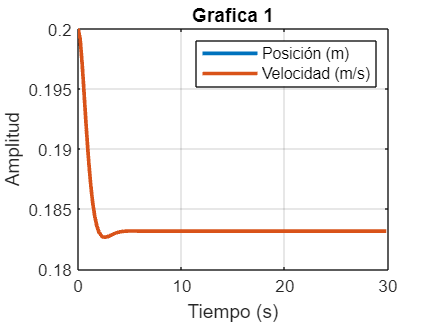

x_inicial = [0;0]; u_inicial = 0; x_inicial_I = 0; %Iniciales.
referencia = 0.2; %era 0.2
A_d = -C*A_discreto; B_d = -C*B_discreto;
%Bucle:
for i=1:Ns %Solo era i=1:Ns
    [t,xd] = ode45('plantafcn_mk1',Ts_,x_inicial,[],kbb,u_inicial);
    x_inicial = xd(end,:)'; % x_a con transpuesta.
    u_inicial = -mat_K*[x_inicial;x_inicial_I]; %Ya no es la inicial si no u[k]...
    x_inicial_I = A_d*x_inicial + B_d*u_inicial + referencia; %xI[k+1]...
    x_sim(i,:) = x_inicial_I'; %era x_inicial_I
    u_sim(i,:) = u_inicial;
end

%Por docente ----->
%for i=1:Ns
%    [t,xd]=ode45('plantafcn',Ts,x_0,[],u);   %tenia kbb,u Simular la planta para un Ts.
%    xmed=xd(end,:)';  % Medir estados (la última señal se toma a los Ts segundos).
%    error=ref-xmed;
%    u=-mat_K*error;       % Cálculo del control y se envía a la planta.
%    x_0=xmed;        % Condiciones inciales para la próxima iteración
%    x_sim(i,:)=xmed';    % Solo almacenar los estados para graficar.
%    usim(i,:)=u;     % Solo almacenar la señal de control para graficar.
%end

%Gráficas:
time=0:Ts_:Ns*Ts_-Ts_;
figure; %subplot(2,1,1); 
plot(time,(x_sim(:,1)),'LineWidth', 2); title('Grafica 1');
xlabel('Tiempo (s)'); ylabel('Amplitud'); grid on;
hold on
plot(time,(x_sim(:,2)),'LineWidth', 2); %title('Grafica 2');
xlabel('Tiempo (s)'); ylabel('Amplitud'); grid on; legend('Posición (m)','Velocidad (m/s)');
hold off
%subplot(2,1,2);

figure;
plot(time,(u_sim),'b','LineWidth', 2); title('Señal de Control');

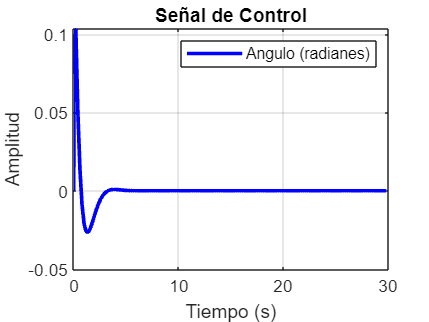

xlabel('Tiempo (s)'); ylabel('Amplitud'); grid on; legend('Angulo (radianes)');

*Para elegir el tiempo puedo ver el tiempo de establecimiento en 5 tao y el Ts es 1/10 de la constante 5 tao.*

Entonces: $\frac{\left(5*\textrm{tao}\right)}{10}=\textrm{Ts},\textrm{entonces}\;\textrm{tao}=\textrm{Ts}*\frac{10}{5}=0\ldotp 2*\frac{10}{5}=0\ldotp 4$. Verificar***